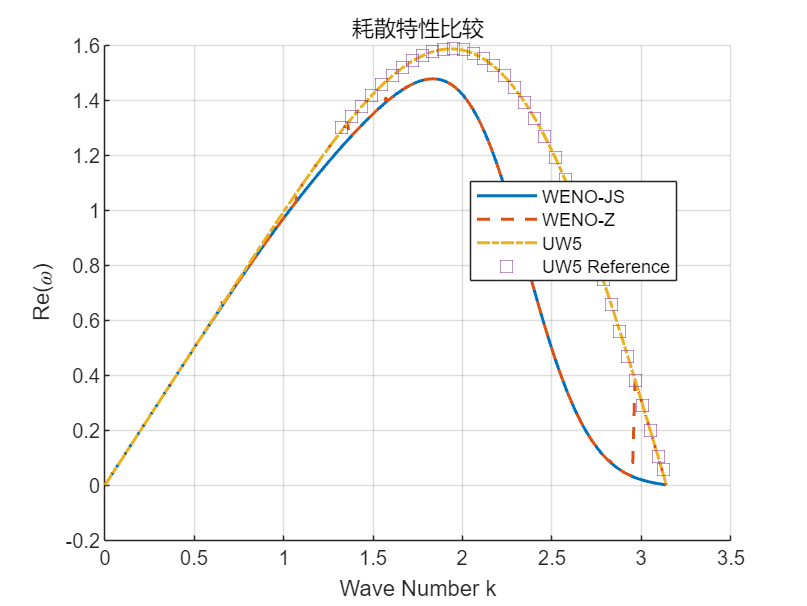

clc ,clear, close all
% 计算三种格式的结果
[W_js, kList] = computeWList(@weno5jse16);  % WENO-JS
[W_ze, ~] = computeWList(@weno5ze16);       % WENO-ZE
[W_uw5, ~] = computeWList(@uw5);            % UW5
data_uw5 = readmatrix("UW5.csv");


% 绘制实部（耗散特性）
figure
hold on
plot(kList, real(W_js), 'LineWidth',1.5, 'DisplayName','WENO-JS')
plot(kList, real(W_ze), '--', 'LineWidth',1.5, 'DisplayName','WENO-Z')
plot(kList, real(W_uw5), '-.', 'LineWidth', 1.5, 'DisplayName', 'UW5')
plot(data_uw5(:,1), data_uw5(:,2), 's', 'MarkerSize',8, 'DisplayName','UW5 Reference')
xlabel('Wave Number k'), ylabel('Re(\omega)')
title('耗散特性比较'), grid on, legend('Location','best')

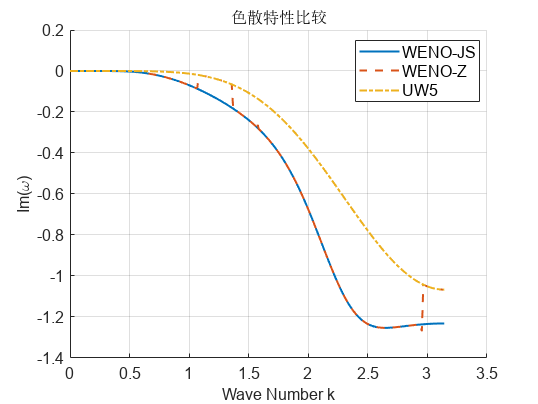


%
% 绘制虚部（色散特性）
figure
hold on
plot(kList, imag(W_js), 'LineWidth',1.5, 'DisplayName','WENO-JS')
plot(kList, imag(W_ze), '--', 'LineWidth',1.5, 'DisplayName','WENO-Z')
plot(kList, imag(W_uw5), '-.', 'LineWidth', 1.5, 'DisplayName', 'UW5')
xlabel('Wave Number k'), ylabel('Im(\omega)')
title('色散特性比较'), grid on, legend('Location','best')

% 统一调整样式
set(findall(gcf,'-property','FontSize'),'FontSize',12)

function [PhiN, phiNList] = computeWList(getDif)

tau = 1e-10;
N = 500;
h = 2*pi/N;

vj_0 = zeros(1, N);
vj_tau = zeros(1, N);
PhiN = zeros(1, N/2+1);

for n = 0:N/2
    nIndex = n+1;
    phiN = 2*pi*n/N;

    for j = 0:N-1
        jIndex = j+1;

        vj_0(jIndex) = exp(1i*j*phiN);

        uavemmm = exp(1i*(j-3)*phiN);
        uavemm = exp(1i*(j-2)*phiN);
        uavem = exp(1i*(j-1)*phiN);
        uave = exp(1i*(j+0)*phiN);
        uavep = exp(1i*(j+1)*phiN);
        uavepp = exp(1i*(j+2)*phiN);

        f_plus  = getDif([uavemm,uavem,uave,uavep,uavepp]);
        f_minus = getDif([uavemmm,uavemm,uavem,uave,uavep]);

        dd = -(f_plus-f_minus)/h;

        vj_tau(jIndex) = vj_0(jIndex) + dd*tau;
    end
    v_tau_hat = 1/N*sum(vj_tau.*exp(-1i*(0:N-1)*phiN));
    sigma = tau/h;
    PhiN(nIndex) = 1i/sigma*log(v_tau_hat);


end

phiNList = (0:N/2)*2*pi/N;
end


function h = uw5(var)
uavemm = var(1);
uavem = var(2);
uave  = var(3);
uavep = var(4);
uavepp = var(5);

h = 1/60*sum([2,-13,47,27,-3].*[uavemm,uavem,uave,uavep,uavepp]);
end

function h = weno5jse16(var)
stencilLeft2 = var(:, 1);
stencilLeft1 = var(:, 2);
centerValue = var(:, 3);
stencilRight1 = var(:, 4);
stencilRight2 = var(:, 5);

epsilon = 1e-16;

% 计算每个模板上的重构值
reconStencil0 = (2*stencilLeft2 - 7*stencilLeft1 + 11*centerValue) / 6;  % 左侧模板
reconStencil1 = (-stencilLeft1 + 5*centerValue + 2*stencilRight1) / 6;   % 中心模板
reconStencil2 = (2*centerValue + 5*stencilRight1 - stencilRight2) / 6;   % 右侧模板

% 计算光滑指示器
smoothness0 = 13/12*(stencilLeft2 - 2*stencilLeft1 + centerValue).^2 ...
    + 1/4*(stencilLeft2 - 4*stencilLeft1 + 3*centerValue).^2;

smoothness1 = 13/12*(stencilLeft1 - 2*centerValue + stencilRight1).^2 ...
    + 1/4*(stencilLeft1 - stencilRight1).^2;

smoothness2 = 13/12*(centerValue - 2*stencilRight1 + stencilRight2).^2 ...
    + 1/4*(3*centerValue - 4*stencilRight1 + stencilRight2).^2;

% 线性权重
d0 = 1/10;
d1 = 6/10;
d2 = 3/10;

% 计算权重
w0 = d0./(epsilon + smoothness0).^2;
w1 = d1./(epsilon + smoothness1).^2;
w2 = d2./(epsilon + smoothness2).^2;

S = w0 + w1 + w2;
w0 = w0./S;
w1 = w1./S;
w2 = w2./S;

% 重构
h = w0.*reconStencil0 + w1.*reconStencil1 + w2.*reconStencil2;

end
function h = weno5ze16(var)
stencilLeft2 = var(:, 1);
stencilLeft1 = var(:, 2);
centerValue = var(:, 3);
stencilRight1 = var(:, 4);
stencilRight2 = var(:, 5);

epsilon = 1e-16;

% 计算每个模板上的重构值
reconStencil0 = (2*stencilLeft2 - 7*stencilLeft1 + 11*centerValue) / 6;  % 左侧模板
reconStencil1 = (-stencilLeft1 + 5*centerValue + 2*stencilRight1) / 6;   % 中心模板
reconStencil2 = (2*centerValue + 5*stencilRight1 - stencilRight2) / 6;   % 右侧模板

% 计算光滑指示器
smoothness0 = 13/12*(stencilLeft2 - 2*stencilLeft1 + centerValue).^2 ...
    + 1/4*(stencilLeft2 - 4*stencilLeft1 + 3*centerValue).^2;

smoothness1 = 13/12*(stencilLeft1 - 2*centerValue + stencilRight1).^2 ...
    + 1/4*(stencilLeft1 - stencilRight1).^2;

smoothness2 = 13/12*(centerValue - 2*stencilRight1 + stencilRight2).^2 ...
    + 1/4*(3*centerValue - 4*stencilRight1 + stencilRight2).^2;

% 线性权重
d0 = 1/10;
d1 = 6/10;
d2 = 3/10;

% 计算权重
tau = abs(smoothness2-smoothness0);
w0 = d0.*(1 + (tau/(epsilon + smoothness0))^2 );
w1 = d1.*(1 + (tau/(epsilon + smoothness1))^2 );
w2 = d2.*(1 + (tau/(epsilon + smoothness2))^2 );

% w0 = d0.*(1 / (epsilon + smoothness0)^2 );
% w1 = d1.*(1 / (epsilon + smoothness1)^2 );
% w2 = d2.*(1 / (epsilon + smoothness2)^2 );


S = w0 + w1 + w2;
w0 = w0./S;
w1 = w1./S;
w2 = w2./S;

% 重构
h = w0.*reconStencil0 + w1.*reconStencil1 + w2.*reconStencil2;

end
